# Level Set

In CORA, level sets are instantiated by 

% ls = levelSet(eq,vars,op);

where `eq` is a symbolic MATLAB function, `vars` are the symbolic variables, and `op` is the comparison operator.

Example:

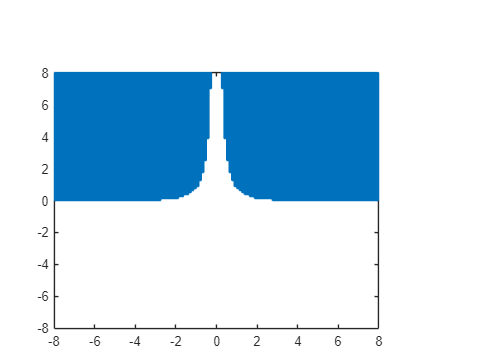

% init figure
figure;
xlim([-8,8])
ylim([-8,8])

% initialize level set
vars = sym('x',[2;1]);
eq = 1/vars(1)^2 - vars(2);
ls = levelSet(eq,vars,'<=');

% plot level set
plot(ls);

For more information, type

help levelSet

  levelSet - class definition for non-linear level sets
 
  Syntax:
     obj = levelSet(eq,vars,compOp)
     obj = levelSet(eq,vars,compOp,solved)
 
  Inputs:
     eq - symbolic equation defining the set (eq == 0 or eq <= 0 or eq < 0)
     vars - symbolic variables
     compOp - operator ('==' or '<=' or '<')
     solved - equation solved for one variable
 
  Outputs:
     obj - generated levelSet object
 
  Example:
     % single equation
     syms x y
     eqs = x^2 + y^2 - 4;
     ls = levelSet(eqs,[x;y],'==');
     
     figure; hold on; xlim([-3,3]); ylim([-3,3]);
     plot(ls,[1,2],'r');
 
     % multiple equations
     syms x y
     eq1 = x^2 + y^2 - 4;
     eq2 = x + y;
     ls = levelSet([eq1;eq2],[x;y],{'<=';'<='});
     
     figure; hold on; xlim([-3,3]); ylim([-3,3]);
     plot(ls,[1,2],'r');
 
  Other m-files required: none
  Subfunctions: none
  MAT-files required: none
